# Actividad práctica: Análisis de señales discretas en el dominio del tiempo

Mes: Julio

Estación: Pedregal

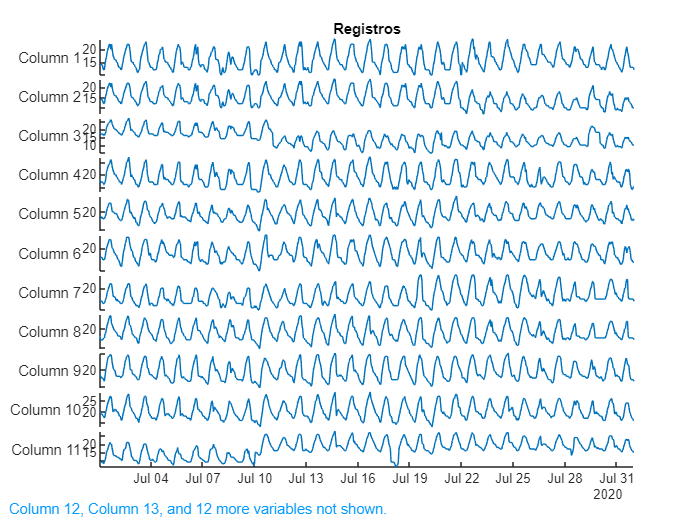

TMP = readtable('TMP_2020_7.csv');
stackedplot(TMP.Timestamp,TMP{:,2:end})
title("Registros")

¿Qué características tienen estas señales (series de tiempo)? 

Tienen comportamientos 

¿Son periódicas o aperiodicas? 

Se observa un comportamiento periodico pero debido a las peturbaciones presentes en algunos días no pueden ser consideradas periodicas

¿Deterministas o estocásticas? 

Las gráficas son estocásticas

% Cálculos

Stations = TMP{:,2:end};
MIN = min(Stations)

MIN =     10     7     5    13     9    10    10     9     9    13     6     5    13    13    10    12    11    13    10    12    11    12    11    14    12


MAX = max(Stations)

MAX =     24    24    27    27    29    26    26    28    30    29    28    21    27    27    24    26    26    29    23    28    27    27    26    28    28


MEAN = mean(Stations)

MEAN =    15.9073   14.6438   14.4140   19.0511   18.6734   17.9892   16.4382   18.0148   19.0202   20.3548   17.5376   12.7634   19.4637   19.0309   16.6062   17.9866   17.9892   20.1304   16.0134   18.9462   18.4005   18.4597   18.0968   20.2769   18.9462


STD = std(Stations)

STD =     3.5540    3.7985    4.6176    3.3644    3.9324    3.5731    3.8580    4.3353    5.2330    3.4785    4.8988    3.7910    3.3909    3.4989    3.2083    3.2624    3.4403    3.4435    3.2404    3.6414    3.7508    3.5014    3.5468    3.3509    3.7628



[Min,p] = min(MIN)

Min = 5

p = 3

[Max, p] = max(MAX)

Max = 30

p = 9


[M_min, p] = max(MEAN)

M_min = 20.3548

p = 10


[STD_max, p] = max(STD)

STD_max = 5.2330

p = 9

ren_prom = mean(Stations')

ren_prom =    16.1600   15.7200   15.6000   15.6400   15.1200   14.6400   14.6000   15.8000   17.4400   19.2400   20.8400   21.9200   23.0800   23.9600   24.6000   24.5600   23.8400   21.5600   20.0000   19.0000   18.6800   18.4400   17.9200   17.2000   17.0000   16.3600   15.8800   15.3200   15.1200   14.6800   14.2000   15.1200   16.8000   18.3200   19.7600   21.1600   22.4800   23.8000   24.7200   25.2400   25.1600   23.1600   20.7600   19.1600   18.4000   17.6400   17.0000   16.3200   15.9200   15.2800


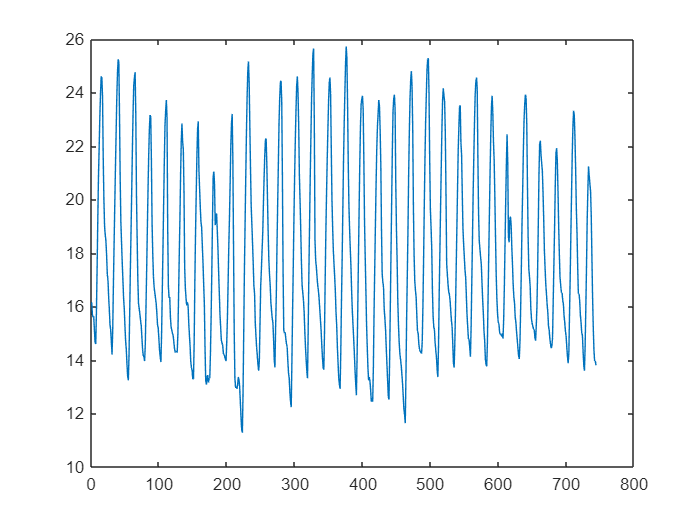

plot(1:length(ren_prom),ren_prom)

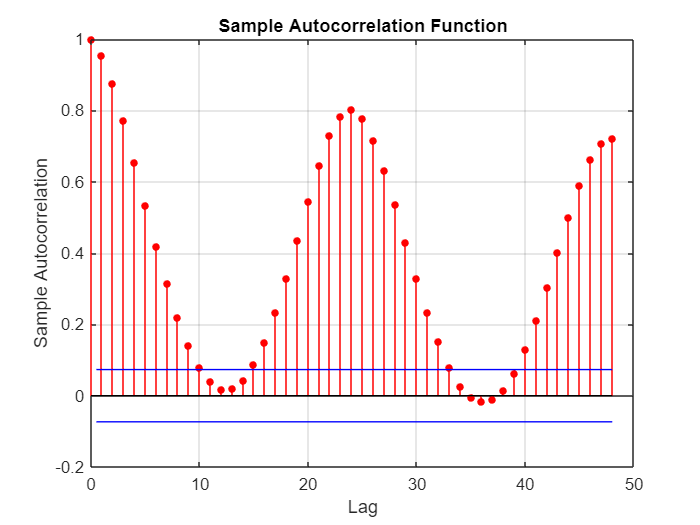

figure
autocorr(TMP.AJU,48)